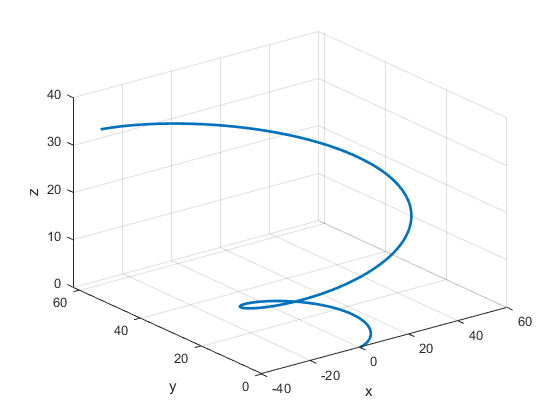

R_0 = [0; 0; 0];  % Anfangsposition (Nullvektor)
V_0 = [0; 0; 0];  % Anfangsgeschwindigkeit (Nullvektor)
t = linspace(0, 120, 240); % Zeitbereich auf eine Minute erweitert

% A ist eine Matrix, die die Beschleunigung in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Beschleunigung wird durch trigonometrische Funktionen erzeugt.
A = [1 * cos(t/12); 0.5 * sin(t/12); 0.05 * ones(size(t/12))]; 

% V ist eine Matrix, die die Geschwindigkeit in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Geschwindigkeit wird durch numerische Integration der Beschleunigung berechnet.
% Die Anfangsgeschwindigkeit V_0 wird hinzugefügt.
V = cumtrapz(t/12, A, 2) + V_0;


% R ist eine Matrix, die die Position in x-, y- und z-Richtung in Abhängigkeit von der Zeit t enthält.
% Die Position wird durch numerische Integration der Geschwindigkeit und Beschleunigung berechnet.
% Der Anfangsposition R_0 und zusätzlichen Ausdrücken für die Berücksichtigung der Beschleunigung während der Bewegung wird hinzugefügt.
R_pos = R_0 + cumtrapz(t/12, V, 2) + 0.5 * cumtrapz(t/12, A, 2) .* t;

figure(1);
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);  % 'LineWidth', 2 legt die Linienbreite des Plots fest.
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

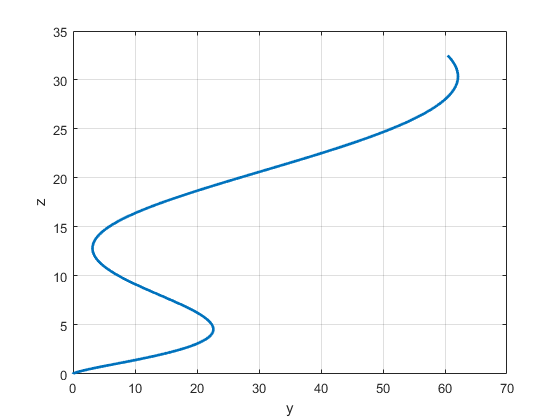

 % Plot der y- und z-Komponenten der Position
figure(2);
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
ylabel('z');
xlabel('y'); 
grid on; 

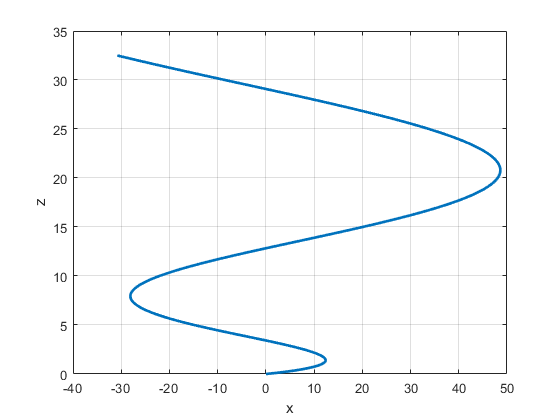


% Plot der x- und z-Komponenten der Position
figure(3);
plot(R_pos(1,:), R_pos(3,:), 'LineWidth', 2); 
ylabel('z');
xlabel('x');
grid on;

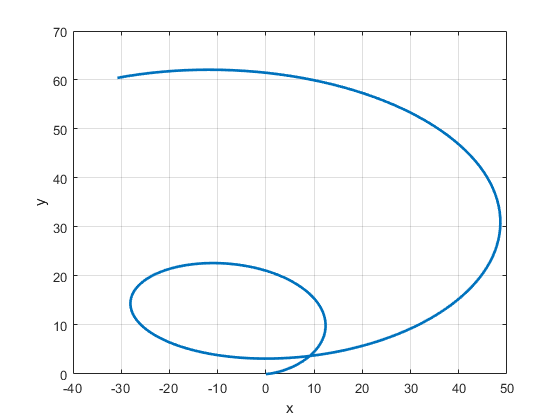


% Plot der x- und y-Komponenten der Position
figure(4);
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2); 
ylabel('y');
xlabel('x');
grid on;

Zwei Radersensoren werden definiert:

Position radar1 = [0, -10, 0]

Position rader2 = [-50, 30, 0]

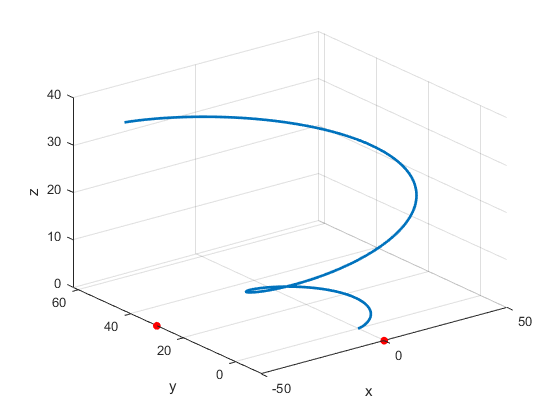

pos_radar1 = [0, -10, 0];  % Position des Radar 1: x=0, y=-10, z=0
pos_radar2 = [-50, 30, 0];  % Position des Radar 2: x=-50, y=30, z=0

figure;
hold on;  % Aktiviert den "hold on"-Modus, um mehrere Plots in derselben Figur zu zeichnen
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);  % Zeichnet den 3D-Plot der Daten R mit Linienbreite 2

% Zeichnet den Punkt für Radar 1 in Rot mit einem Marker der Größe 20
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);

% Zeichnet den Punkt für Radar 2 in Rot mit einem Marker der Größe 20
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);

xlabel('x');
ylabel('y');
zlabel('z');
grid on;
view(3);
hold off;

R_transposed = transpose(R_pos);  % Transponiert die Matrix R

dist_matrix_radar1 = [];
dist_matrix_radar2 = [];

dist_3dmatrix_radar1 = [];
dist_3dmatrix_radar2 = [];

for i = 1:length(R_transposed)
    
    %Berechnung des Absoluten Abstand im 3D-Raum
    dist_radar1 = norm(R_transposed(i, :) - pos_radar1);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar1
    dist_radar2 = norm(R_transposed(i, :) - pos_radar2);  % Berechnet den Abstand zwischen der i-ten Zeile von R_transposed und pos_radar2
    
    dist_matrix_radar1 = [dist_matrix_radar1; dist_radar1];  % Fügt den Abstand dist_radar1 der dist_matrix_radar1 hinzu
    dist_matrix_radar2 = [dist_matrix_radar2; dist_radar2];  % Fügt den Abstand dist_radar2 der dist_matrix_radar2 hinzu
    
    %Berechnung des Abstands seperat in x,y,z Richtung
    dist3d_radar1 = [R_pos(1,i)-pos_radar1(1), R_pos(2,i)-pos_radar1(2), R_pos(3,i)-pos_radar1(3)];  % Berechnet den 3D-Abstand zwischen R(:,i) und pos_radar1
    dist3d_radar2 = [R_pos(1,i)-pos_radar2(1), R_pos(2,i)-pos_radar2(2), R_pos(3,i)-pos_radar2(3)];  % Berechnet den 3D-Abstand zwischen R(:,i) und pos_radar2
    
    dist_3dmatrix_radar1 = [dist_3dmatrix_radar1; dist3d_radar1];  % Fügt den 3D-Abstand dist3d_radar1 der dist_3dmatrix_radar1 hinzu
    dist_3dmatrix_radar2 = [dist_3dmatrix_radar2; dist3d_radar2];  % Fügt den 3D-Abstand dist3d_radar2 der dist_3dmatrix_radar2 hinzu

end

dist_matrix_radar1  % Gibt die dist_matrix_radar1 aus

dist_matrix_radar1 =    10.0000
   10.0001
   10.0010
   10.0037
   10.0091
   10.0185
   10.0332
   10.0546
   10.0843
   10.1238


dist_matrix_radar2  % Gibt die dist_matrix_radar2 aus

dist_matrix_radar2 =    58.3095
   58.3192
   58.3480
   58.3955
   58.4612
   58.5445
   58.6448
   58.7616
   58.8940
   59.0414



dist_3dmatrix_radar1  % Gibt die dist_3dmatrix_radar1 aus

dist_3dmatrix_radar1 =          0   10.0000         0
    0.0114   10.0001    0.0006
    0.0455   10.0009    0.0023
    0.1021   10.0031    0.0051
    0.1812   10.0074    0.0091
    0.2824   10.0145    0.0142
    0.4055   10.0249    0.0205
    0.5499   10.0395    0.0279
    0.7152   10.0589    0.0364
    0.9008   10.0836    0.0461


dist_3dmatrix_radar2  % Gibt die dist_3dmatrix_radar2 aus

dist_3dmatrix_radar2 =    50.0000  -30.0000         0
   50.0114  -29.9999    0.0006
   50.0455  -29.9991    0.0023
   50.1021  -29.9969    0.0051
   50.1812  -29.9926    0.0091
   50.2824  -29.9855    0.0142
   50.4055  -29.9751    0.0205
   50.5499  -29.9605    0.0279
   50.7152  -29.9411    0.0364
   50.9008  -29.9164    0.0461


theta_radar1 = [];  % Leerer Vektor für die Azimutwinkel von Radar 1
theta_radar2 = [];  % Leerer Vektor für die Azimutwinkel von Radar 2

phi_radar1 = [];  % Leerer Vektor für die Elevationswinkel von Radar 1
phi_radar2 = [];  % Leerer Vektor für die Elevationswinkel von Radar 2

for i = 1:length(R_transposed)
    
    % Berechnung des Elevationswinkels (phi) für Radar 1
    delta_z = R_transposed(i,3) - pos_radar1(3);
    rho = sqrt((R_transposed(i,1) - pos_radar1(1))^2 + (R_transposed(i,2) - pos_radar1(2))^2 + delta_z^2);
    phi_radar1 = [phi_radar1; rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar1 hinzu
    
    % Berechnung des Elevationswinkels (phi) für Radar 2
    delta_z = R_transposed(i,3) - pos_radar2(3);
    rho = sqrt((R_transposed(i,2) - pos_radar2(2))^2 + (R_transposed(i,1) - pos_radar2(1))^2 + delta_z^2);
    phi_radar2 = [phi_radar2; rad2deg(acos(delta_z/rho))];  % Fügt den Winkel zu phi_radar2 hinzu
    
    
    % Berechnung des Azimutwinkels (theta) für Radar 1
    delta_x = R_transposed(i,1) - pos_radar1(1);
    delta_y = R_transposed(i,2) - pos_radar1(2);
    theta_radar1 = [theta_radar1; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar1 hinzu
    
    % Berechnung des Azimutwinkels (theta) für Radar 2
    delta_x = R_transposed(i,2) - pos_radar2(2);
    delta_y = R_transposed(i,1) - pos_radar2(1);
    theta_radar2 = [theta_radar2; rad2deg(atan2(delta_y, delta_x))];  % Fügt den Winkel zu theta_radar2 hinzu   
end

phi_radar1  % Gibt die Elevationswinkel von Radar 1 aus

phi_radar1 =    90.0000
   89.9967
   89.9870
   89.9707
   89.9479
   89.9187
   89.8830
   89.8411
   89.7931
   89.7392


phi_radar2  % Gibt die Elevationswinkel von Radar 2 aus

phi_radar2 =    90.0000
   89.9994
   89.9978
   89.9950
   89.9911
   89.9861
   89.9800
   89.9728
   89.9646
   89.9553



theta_radar1  % Gibt die Azimutwinkel von Radar 1 aus

theta_radar1 =    90.0000
   89.9348
   89.7396
   89.4150
   88.9625
   88.3845
   87.6839
   86.8650
   85.9332
   84.8952


theta_radar2  % Gibt die Azimutwinkel von Radar 2 aus

theta_radar2 =   120.9638
  120.9579
  120.9400
  120.9096
  120.8661
  120.8094
  120.7391
  120.6549
  120.5567
  120.4444


polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1]

polar_koordinaten_radar1 =    10.0000   90.0000   90.0000
   10.0001   89.9348   89.9967
   10.0010   89.7396   89.9870
   10.0037   89.4150   89.9707
   10.0091   88.9625   89.9479
   10.0185   88.3845   89.9187
   10.0332   87.6839   89.8830
   10.0546   86.8650   89.8411
   10.0843   85.9332   89.7931
   10.1238   84.8952   89.7392


polar_koordinaten_radar2 = [dist_matrix_radar2, theta_radar2, phi_radar2]

polar_koordinaten_radar2 =    58.3095  120.9638   90.0000
   58.3192  120.9579   89.9994
   58.3480  120.9400   89.9978
   58.3955  120.9096   89.9950
   58.4612  120.8661   89.9911
   58.5445  120.8094   89.9861
   58.6448  120.7391   89.9800
   58.7616  120.6549   89.9728
   58.8940  120.5567   89.9646
   59.0414  120.4444   89.9553


% Polarkoordinaten für Radar 1: polar_koordinaten_radar1 = [dist_matrix_radar1, theta_radar1, phi_radar1]
% Polarkoordinaten für Radar 2: polar_koordinaten_radar2 = [dist_matrix_radar2, theta_radar2, phi_radar2]

% Berechnung der kartesischen Koordinaten für Radar 1
x_radar1 = polar_koordinaten_radar1(:, 1) .* sin(deg2rad(polar_koordinaten_radar1(:, 3))) .* cos(deg2rad(polar_koordinaten_radar1(:, 2)));
y_radar1 = polar_koordinaten_radar1(:, 1) .* sin(deg2rad(polar_koordinaten_radar1(:, 3))) .* sin(deg2rad(polar_koordinaten_radar1(:, 2)));
z_radar1 = polar_koordinaten_radar1(:, 1) .* cos(deg2rad(polar_koordinaten_radar1(:, 3)));

% Berechnung der kartesischen Koordinaten für Radar 2
x_radar2 = polar_koordinaten_radar2(:, 1) .* sin(deg2rad(polar_koordinaten_radar2(:, 3))) .* cos(deg2rad(polar_koordinaten_radar2(:, 2)));
y_radar2 = polar_koordinaten_radar2(:, 1) .* sin(deg2rad(polar_koordinaten_radar2(:, 3))) .* sin(deg2rad(polar_koordinaten_radar2(:, 2)));
z_radar2 = polar_koordinaten_radar2(:, 1) .* cos(deg2rad(polar_koordinaten_radar2(:, 3)));

% Kombinieren der kartesischen Koordinaten für Radar 1
kartesische_koordinaten_radar1 = [x_radar1, y_radar1, z_radar1];

% Kombinieren der kartesischen Koordinaten für Radar 2
kartesische_koordinaten_radar2 = [x_radar2, y_radar2, z_radar2];


figure;
hold on;
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
plot3(pos_radar1(1), pos_radar1(2), pos_radar1(3), 'r.', 'MarkerSize', 20);
plot3(pos_radar2(1), pos_radar2(2), pos_radar2(3), 'r.', 'MarkerSize', 20);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;
view(3);
hold off;



% x2 = R_transposed(i,1);
% y2 = R_transposed(i,2);
% z2 = R_transposed(i,3);



% % Berechnung des Winkels in Radiant
% alpha_rad = atan2(delta_z, sqrt(delta_x^2 + delta_y^2));
% 
% % Umrechnung des Winkels in Grad
% alpha_deg = rad2deg(alpha_rad);
% 
% % Ausgabe des Winkels
% disp(alpha_deg);
















% Zustandsvektor (x)
x = [];  % Hier musst du die Zustandsvariablen entsprechend deines Systems definieren

% Zustandsübergangsmatrix (F)
F = eye(size(x, 1));  % Hier verwenden wir eine Einheitsmatrix, da der Code keinen expliziten Zustandsübergang definiert

% Beobachtungsmatrix (H)
H = eye(size(x, 1));  % Hier verwenden wir eine Einheitsmatrix, da jede Zustandsvariable direkt beobachtet wird
% Du musst die Beobachtungsmatrix entsprechend anpassen, um die Beziehung zwischen den Zustandsvariablen und den Beobachtungen korrekt darzustellen

% Prozessrauschkovarianz (Q)
Q = diag([0.1, 0.1, 0.1]);  % Hier musst du die Prozessrauschkovarianzmatrix entsprechend der Dynamik deines Systems definieren

% Messrauschkovarianz (R)
R = diag([1, 1, 1, 1, 1, 1]);  % Hier verwenden wir eine Beispiel-Rauschkovarianzmatrix mit gleichen Varianzen für alle Beobachtungen
% Du musst die Messrauschkovarianzmatrix entsprechend der Unsicherheit deiner Messungen anpassen

% Eingangsvektor (u)
u = [];  % Hier musst du den Eingangsvektor definieren, falls du exogene Größen hast, die das System beeinflussen

% Verwende die Matrizen wie gewünscht im Extended Kalman Filter
% ...




% Zustandsvektor (x)
x = [];  % Hier musst du die Zustandsvariablen entsprechend deines Systems definieren

% Zustandsübergangsmatrix (F)
F = eye(size(x, 1));  % Hier verwenden wir eine Einheitsmatrix, da der Code keinen expliziten Zustandsübergang definiert

% Beobachtungsmatrix (H)
H = eye(size(x, 1));  % Hier verwenden wir eine Einheitsmatrix, da jede Zustandsvariable direkt beobachtet wird
% Du musst die Beobachtungsmatrix entsprechend anpassen, um die Beziehung zwischen den Zustandsvariablen und den Beobachtungen korrekt darzustellen

% Prozessrauschkovarianz (Q)
Q = diag([0.1, 0.1, 0.1]);  % Hier musst du die Prozessrauschkovarianzmatrix entsprechend der Dynamik deines Systems definieren

% Messrauschen
R_radar1 = diag([0.1, 0.1, 0.1]);  % Rauschkovarianzmatrix für Radar 1 (angepasst an Ihren Anwendungsfall)
R_radar2 = diag([0.1, 0.1, 0.1]);  % Rauschkovarianzmatrix für Radar 2 (angepasst an Ihren Anwendungsfall)

% Eingangsvektor (u)
u = [];  % Hier musst du den Eingangsvektor definieren, falls du exogene Größen hast, die das System beeinflussen

% Verwende die Matrizen wie gewünscht im Extended Kalman Filter
% ...



% Erweiterter Kalman-Filter für die Positionsschätzung des Helikopters

% Initialisierung der Filterzustände
x_hat = [0; 0; 0];  % Anfangsschätzung der Position (Nullvektor)
P = eye(3);  % Anfangsschätzung der Fehlerkovarianzmatrix (Einheitsmatrix)

% Prozessrauschen
Q = diag([0.1, 0.1, 0.1]);  % Prozessrauschkovarianzmatrix (angepasst an Ihren Anwendungsfall)

% Messrauschen
R_radar1 = diag([0.1, 0.1, 0.1]);  % Rauschkovarianzmatrix für Radar 1 (angepasst an Ihren Anwendungsfall)
R_radar2 = diag([0.1, 0.1, 0.1]);  % Rauschkovarianzmatrix für Radar 2 (angepasst an Ihren Anwendungsfall)

estimated_positions = zeros(3, length(R_transposed));


% Schleife zur Aktualisierung des Filters für jede Messung
for i = 1:length(R_transposed)
    % Vorhersageschritt (Schätzung der aktuellen Position basierend auf der vorherigen Schätzung und der Systemdynamik)
    x_hat_minus = R_pos(:, i);  % Vorhersage der Position basierend auf der vorherigen Schätzung
    %x_hat_minus = x_hat_minus(1:3);
    % Jacobimatrix der Systemdynamik (Ableitung der Zustandsgleichungen nach den Zuständen)
    F = eye(3);  % Für lineare Systeme ist die Jacobimatrix F die Einheitsmatrix
    
    % Fehlerkovarianzvorhersage (Aktualisierung der Fehlerkovarianzmatrix basierend auf der Systemdynamik)
    P_minus = F * P * F' + Q;
    
    % Messungsschritt (Aktualisierung der Schätzung basierend auf der aktuellen Messung)
    z_radar1 = polar_koordinaten_radar1(i, :)';  % Aktuelle Messung von Radar 1
    z_radar2 = polar_koordinaten_radar2(i, :)';  % Aktuelle Messung von Radar 2
    
    % Jacobimatrix der Messfunktion für Radar 1 (Ableitung der Messgleichungen nach den Zuständen)
    H_radar1 = h_x(x_hat, pos_radar1);  % Für die Umwandlung von Polarkoordinaten in kartesische Koordinaten ist die Jacobimatrix H_radar1 die Einheitsmatrix
    
    % Jacobimatrix der Messfunktion für Radar 2 (Ableitung der Messgleichungen nach den Zuständen)
    H_radar2 = h_x(x_hat, pos_radar2);  % Für die Umwandlung von Polarkoordinaten in kartesische Koordinaten ist die Jacobimatrix H_radar2 die Einheitsmatrix
    
    
    y_radar1 = z_radar1 - H_radar1 .* x_hat_minus;  % Adjusted for matrix multiplication
    y_radar2 = z_radar2 - H_radar2 .* x_hat_minus;  % Adjusted for matrix multiplication

    
    % Innovationskovarianz (Kombination der Fehlerkovarianz des Filters und des Messrauschens)
    S_radar1 = H_radar1 .* P_minus .* H_radar1' + R_radar1;
    S_radar2 = H_radar2 .* P_minus .* H_radar2' + R_radar2;
    
    % Kalman-Gain-Berechnung (Gewichtung des Innovationsvektors basierend auf der Innovationskovarianz)
    K_radar1 = P_minus .* H_radar1' * inv(S_radar1);
    K_radar2 = P_minus .* H_radar2' * inv(S_radar2);
    
    % Aktualisierung der Schätzung (Korrektur der Vorhersage basierend auf der Messung)
    x_hat = x_hat_minus + K_radar1 * y_radar1 + K_radar2 * y_radar2;
    
    % Aktualisierung der Fehlerkovarianzmatrix (Korrektur der Fehlerkovarianzvorhersage basierend auf der Messung)
    P = (eye(3) - K_radar1 * H_radar1) * P_minus * (eye(3) - K_radar1 * H_radar1)' + K_radar1 * R_radar1 * K_radar1' + ...
        (eye(3) - K_radar2 * H_radar2) * P_minus * (eye(3) - K_radar2 * H_radar2)' + K_radar2 * R_radar2 * K_radar2';
    
    % Speichern Sie die geschätzte Position für den aktuellen Schritt
    estimated_positions(:, i) = x_hat(1:3);
end

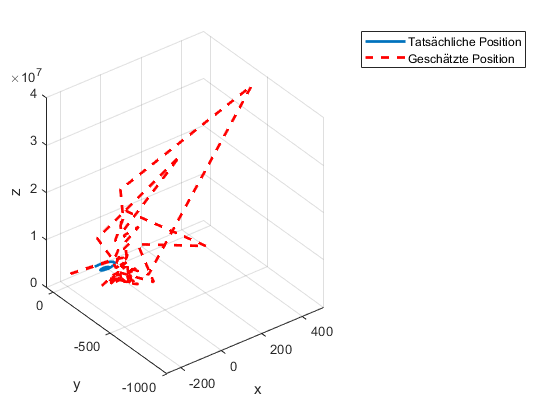


% Plotten der geschätzten Positionen im Vergleich zu den tatsächlichen Positionen
figure;
plot3(R_pos(1,:), R_pos(2,:), R_pos(3,:), 'LineWidth', 2);  % Tatsächliche Positionen
hold on;
plot3(estimated_positions(1,:), estimated_positions(2,:), estimated_positions(3,:), 'r--', 'LineWidth', 2);  % Geschätzte Positionen
xlabel('x');
ylabel('y');
zlabel('z');
legend('Tatsächliche Position', 'Geschätzte Position');
grid on;

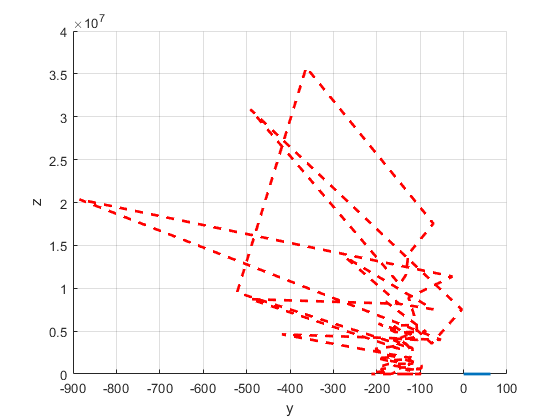


 % Plot der y- und z-Komponenten der Position
figure;
hold on;
plot(R_pos(2,:), R_pos(3,:), 'LineWidth', 2);
plot(estimated_positions(2,:), estimated_positions(3,:), 'r--', 'LineWidth', 2);  % Geschätzte Positionen
ylabel('z');
xlabel('y'); 
grid on; 
hold off;

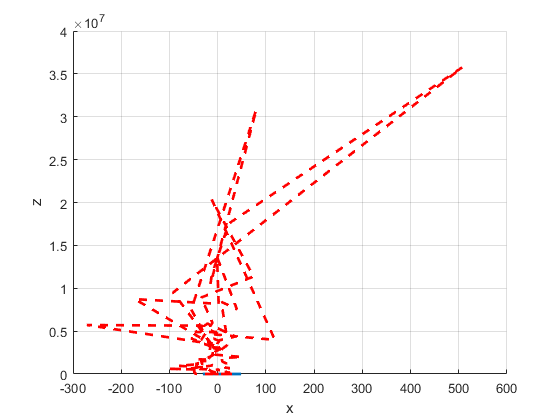


% Plot der x- und z-Komponenten der Position
figure;
hold on;
plot(R_pos(1,:), R_pos(3,:), 'LineWidth', 2);
plot(estimated_positions(1,:), estimated_positions(3,:), 'r--', 'LineWidth', 2);  % Geschätzte Positionen
ylabel('z');
xlabel('x');
grid on;
hold off;

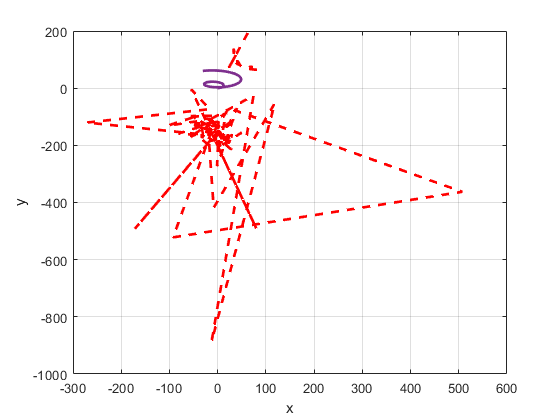

% Plot der x- und y-Komponenten der Position
figure(4);
hold on;
plot(R_pos(1,:), R_pos(2,:), 'LineWidth', 2);
plot(estimated_positions(1,:), estimated_positions(2,:), 'r--', 'LineWidth', 2);  % Geschätzte Positionen
ylabel('y');
xlabel('x');
grid on;
hold off;

function h = h_x(x, radar_position)
    % Umwandlung von Kartesischen Koordinaten in Polarkoordinaten
    h = zeros(3,1);
    dx = x(1) - radar_position(1);
    dy = x(2) - radar_position(2);
    dz = x(3) - radar_position(3);
    h(1) = sqrt(dx^2 + dy^2 + dz^2);                      % Entfernung
    h(2) = atan2(dy, dx);                                  % Azimutwinkel Theta
    h(3) = atan2(sqrt(dx^2 + dy^2), dz);                   % Elevationwinkel Phi
end